spoofingdetection

prnnums =      3
     6
     7
    10
    11
    13
    16
    19
    20
    23


## Plotting Measurements

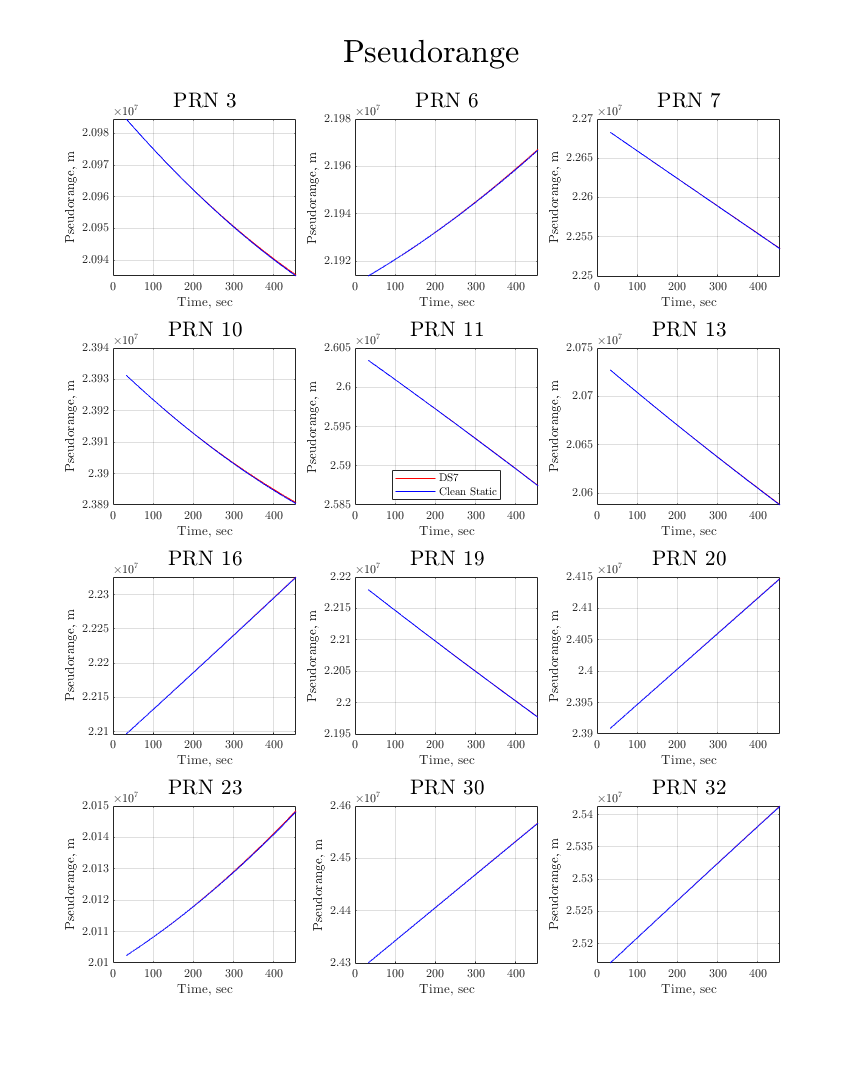

figure(1)
for i = 1:length(prnnums)
    subplot(4,3,i)
    plot(RRT,cn0(:,i),'r')
    hold on
    plot(RRT,cn0_cs(:,i),'b')
    grid on
    title("PRN "+num2str(prnnums(i)),'fontsize',stfsize)
    xlabel('Time, sec')
    ylabel('C/N0, dB-Hz')
    if prnnums(i) == 11
        legend("DS7","Clean Static",'Location',"best")
    end
    hold off
end
set(gcf,'position',[0,0,width,height])
sgtitle("Signal to Noise Ratio",'fontsize',tfsize)

figure(2)
for i = 1:length(prnnums)
    subplot(4,3,i)
    plot(RRT,prange(:,i),'r')
    hold on
    plot(RRT,prange_cs(:,i),'b')
    grid on
    title("PRN "+num2str(prnnums(i)),'fontsize',stfsize)
    xlabel('Time, sec')
    ylabel('Pseudorange, m')
    if prnnums(i) == 11
        legend("DS7","Clean Static",'Location',"best")
    end
    hold off
end
set(gcf,'position',[0,0,width,height])
sgtitle("Pseudorange",'fontsize',tfsize)

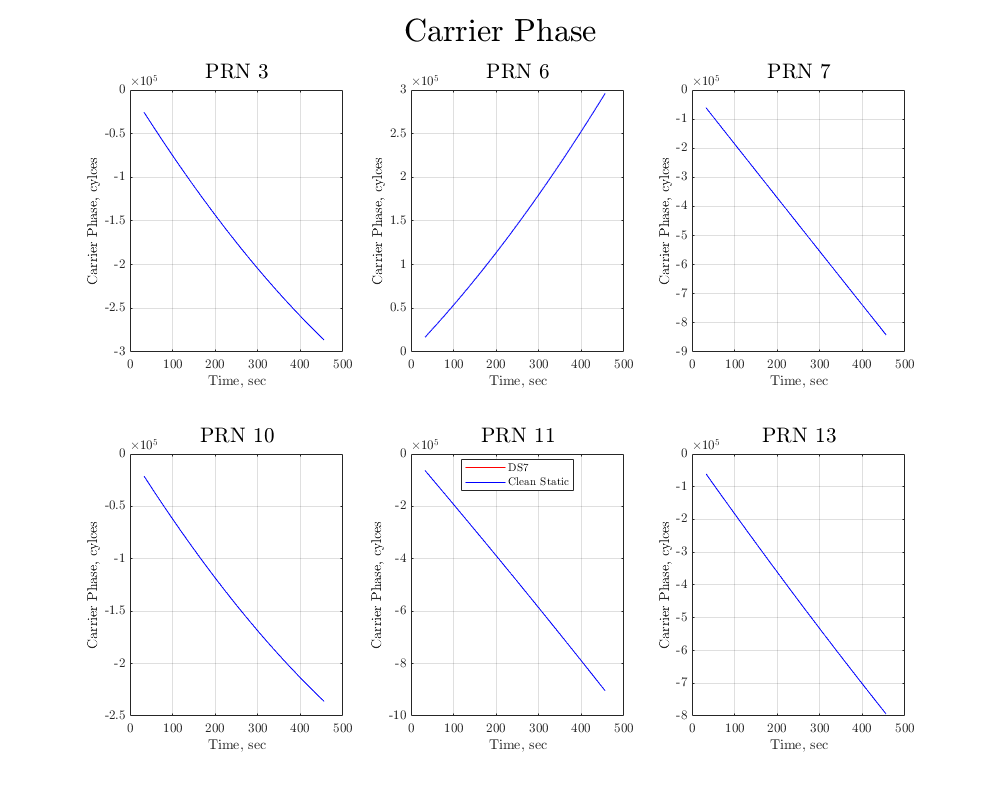


figure(3)
for i = 1:6
    subplot(2,3,i)
    plot(RRT,cphase(:,i),'r')
    hold on
    plot(RRT,cphase_cs(:,i),'b')
    grid on
    title("PRN "+num2str(prnnums(i)),'fontsize',stfsize)
    xlabel('Time, sec')
    ylabel('Carrier Phase, cylces')
    if prnnums(i) == 11
        legend("DS7","Clean Static",'Location',"best")
    end
    hold off
end
set(gcf,'position',[0,0,1000,800])
sgtitle("Carrier Phase",'fontsize',tfsize)

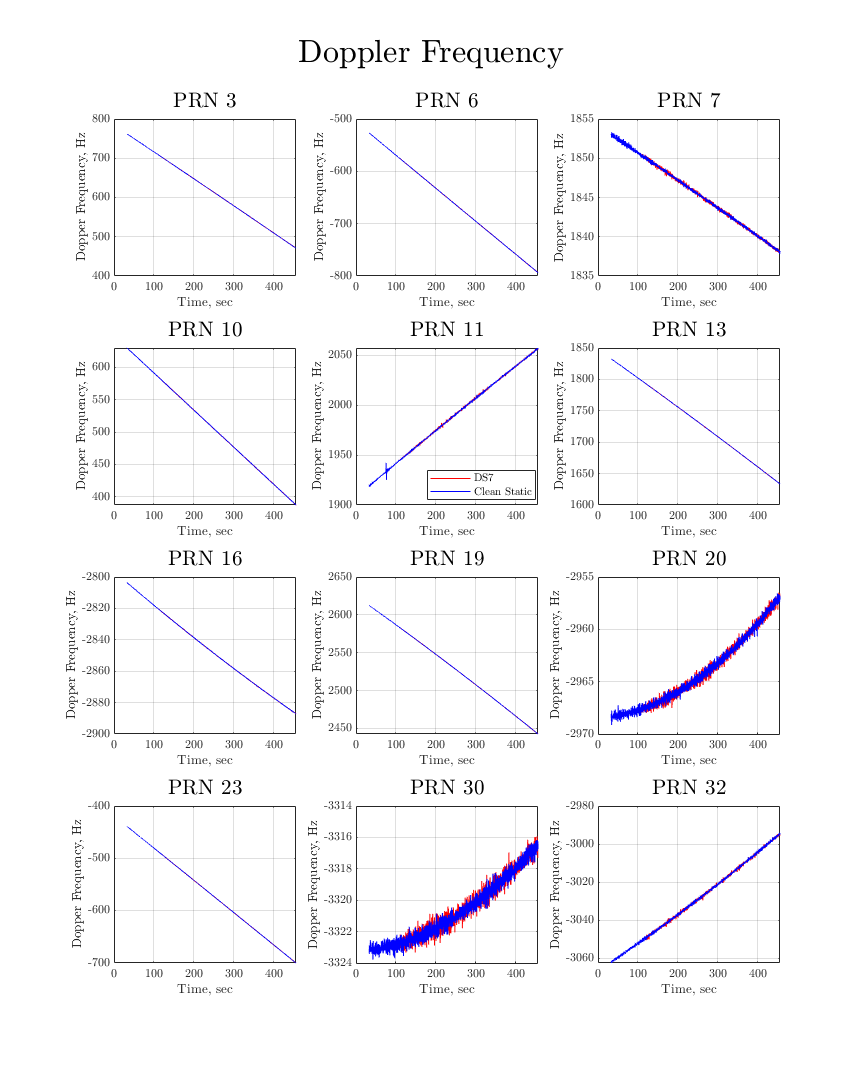


figure(4)
for i = 1:length(prnnums)
    subplot(4,3,i)
    plot(RRT,dop(:,i),'r')
    hold on
    plot(RRT,dop_cs(:,i),'b')
    grid on
    title("PRN "+num2str(prnnums(i)),'fontsize',stfsize)
    xlabel('Time, sec')
    ylabel('Dopper Frequency, Hz')
    if prnnums(i) == 11
        legend("DS7","Clean Static",'Location',"best")
    end
    hold off
end
set(gcf,'position',[0,0,width,height])
sgtitle("Doppler Frequency",'fontsize',tfsize)

## Plotting Navigation Solution

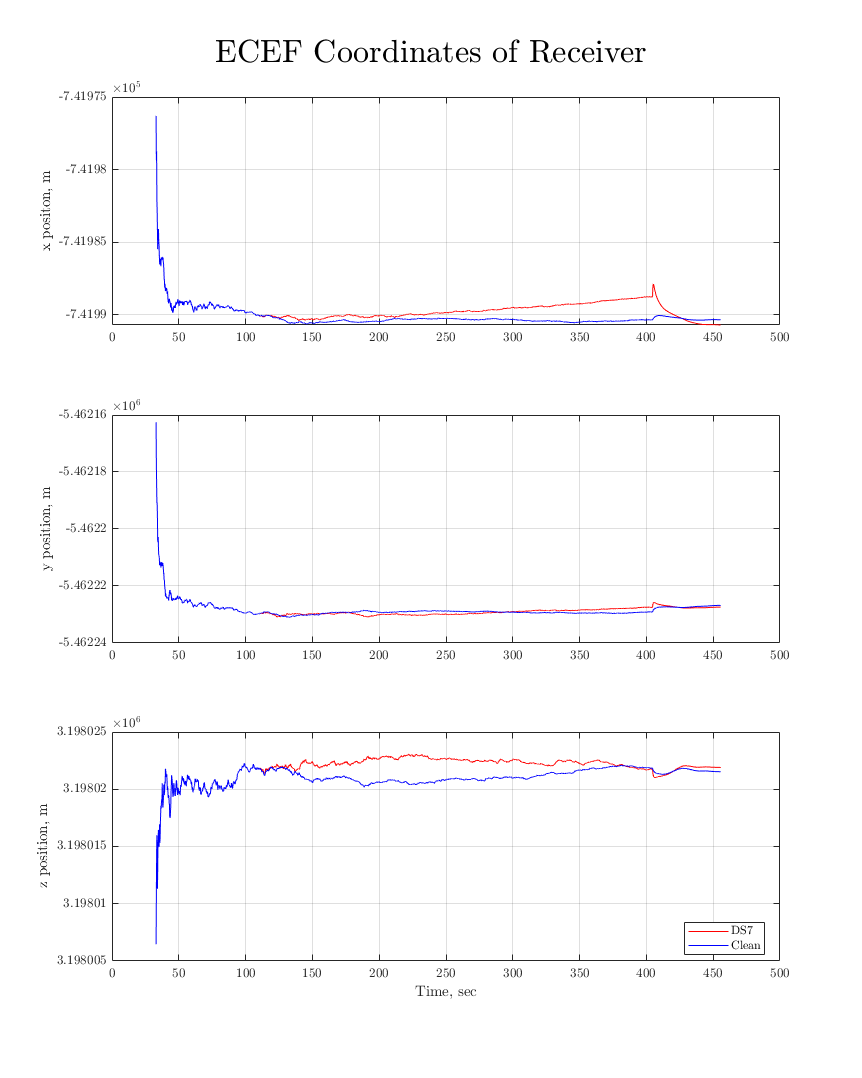

% position
figure(5)
subplot(3,1,1)
plot(RRT,x,'r')
hold on
plot(RRT,x_cs,'b')
grid on
ylabel("x positon, m")
hold off

subplot(3,1,2)
plot(RRT,y,'r')
hold on
plot(RRT,y_cs,'b')
grid on
ylabel('y position, m')
hold off

subplot(3,1,3)
plot(RRT,z,'r')
hold on
plot(RRT,z_cs,'b')
grid on
ylabel('z position, m')
xlabel('Time, sec')
legend('DS7','Clean','Location',"best")
hold off
sgtitle('ECEF Coordinates of Receiver','fontsize',tfsize)
set(gcf,'position',[0,0,width,height])

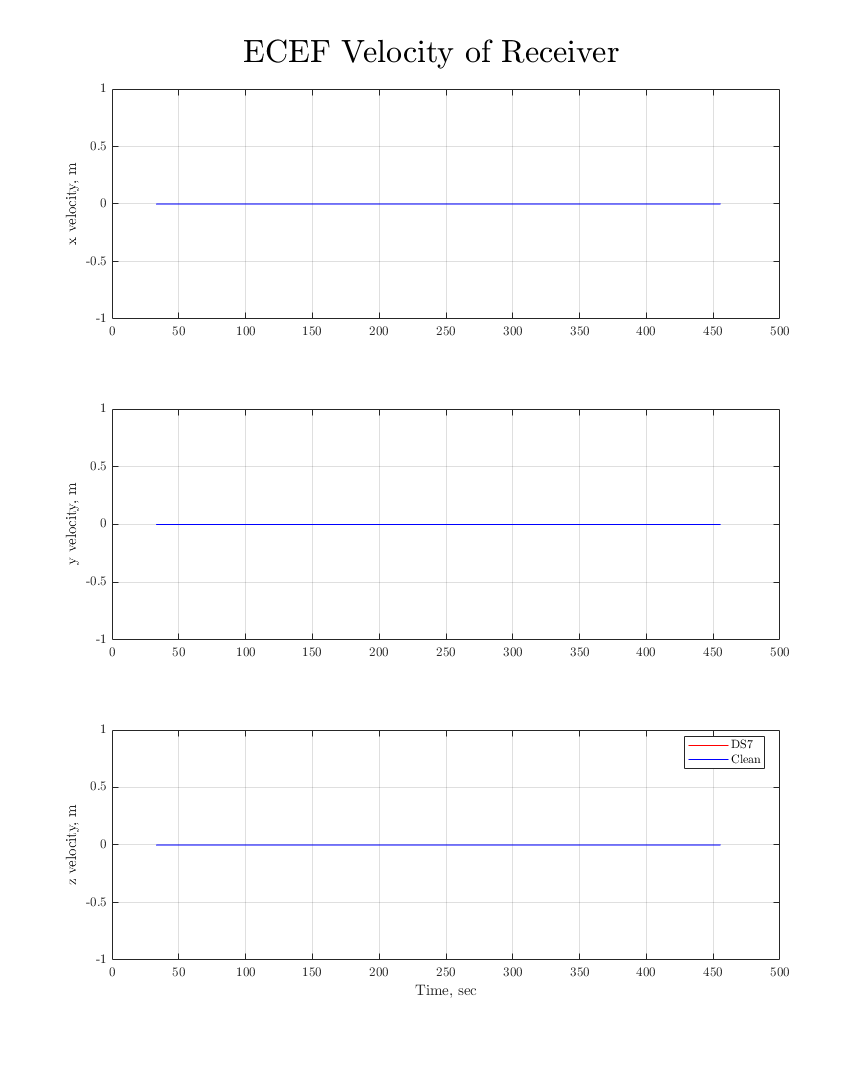


% Velocity
figure(6)
subplot(3,1,1)
plot(RRT,xd,'r')
hold on
plot(RRT,xd_cs,'b')
grid on
ylabel("x velocity, m")
hold off

subplot(3,1,2)
plot(RRT,yd,'r')
hold on
plot(RRT,yd_cs,'b')
grid on
ylabel('y velocity, m')
hold off

subplot(3,1,3)
plot(RRT,zd,'r')
hold on
plot(RRT,zd_cs,'b')
grid on
ylabel('z velocity, m')
xlabel('Time, sec')
legend('DS7','Clean','Location',"best")
hold off
sgtitle('ECEF Velocity of Receiver','fontsize',tfsize)
set(gcf,'position',[0,0,width,height])

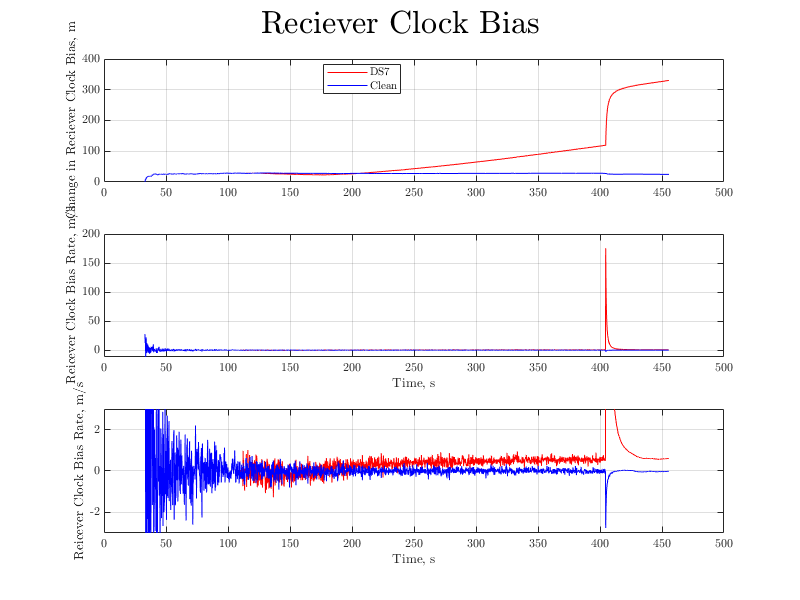


% Reciever Clock
figure(7)
subplot(3,1,1)
plot(RRT,dR-dR(1),'r')
hold on
plot(RRT,dR_cs-dR_cs(1),'b')
grid on
ylabel('Change in Reciever Clock Bias, m')
legend('DS7','Clean','Location',"best")
hold off

dRdt = intdiff(dR,RRT);
dRdt_cs = intdiff(dR_cs,RRT);
subplot(3,1,2)
plot(RRT,dRdt,'r')
hold on
plot(RRT,dRdt_cs,'b')
xlabel('Time, s')
ylabel('Reicever Clock Bias Rate, m/s')
grid on
hold off

dRdt = intdiff(dR,RRT);
dRdt_cs = intdiff(dR_cs,RRT);
subplot(3,1,3)
plot(RRT,dRdt,'r')
hold on
plot(RRT,dRdt_cs,'b')
xlabel('Time, s')
ylabel('Reicever Clock Bias Rate, m/s')
ylim([-3,3])
grid on
hold off
sgtitle('Reciever Clock Bias','fontsize',tfsize)
set(gcf,'position',[0,0,800,600])

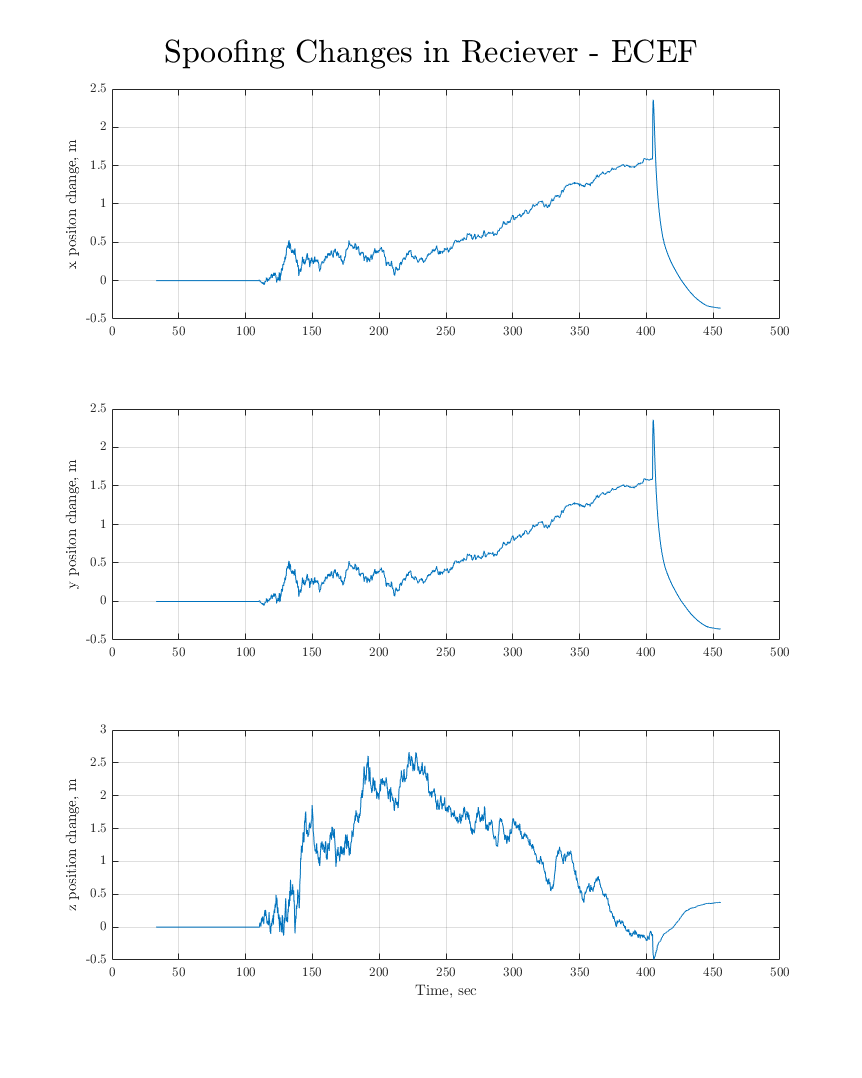


% Position Changes
figure(8)
subplot(3,1,1)
plot(RRT,x-x_cs)
grid on
ylabel("x positon change, m")

subplot(3,1,2)
plot(RRT,x-x_cs)
grid on
ylabel("y positon change, m")

subplot(3,1,3)
plot(RRT,z-z_cs)
grid on
ylabel('z position change, m')
xlabel('Time, sec')
sgtitle('Spoofing Changes in Reciever - ECEF','fontsize',tfsize)
set(gcf,'position',[0,0,width,height])

## Plotting Satellite Information

% saveas(1,'cn0.jpg')
% saveas(2,'prange.jpg')
% saveas(3,'cphase.jpg')
% saveas(4,'dop.jpg')
% saveas(5,'pos.jpg')
% saveas(6,'vel.jpg')
% saveas(7,'rclock.jpg')
% saveas(8,'dpos.jpg')
